Import raw data

addpath(genpath('./'))
%iniData = readtabe('raw.txt', 'Delimiter', '\t', 'ReadRowNames', true, 'ReadVariableNames',true);
%disp(iniData)
%insertformattxt()%
%iniData = readtable('output_file.txt', 'Delimiter', '\t', 'ReadRowNames', true, 'ReadVariableNames',true);
%iniData = readtable('scRNAseq.txt');
iniData = readtable('gene_cell.csv');
disp(size(iniData))

       10000        4000




% iniData(1, :) = [];
matrix_data=table2array(iniData)

matrix_data =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     




%[~, unique_indices, ~] = unique(matrix_data, 'rows', 'stable');
%duplicate_indices = setdiff(1:size(matrix_data, 1), unique_indices);



Preprocessing 

tic;
minGenes = 0; minCells = 0; libararyflag = 0; logNormalize = 1;  
proData = preprocessing(iniData, minCells, minGenes, libararyflag,logNormalize);
M=proData.data

M =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.6021         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

Select informative genes used for cell partitioning

fano
ggggggggggggggg
        5041



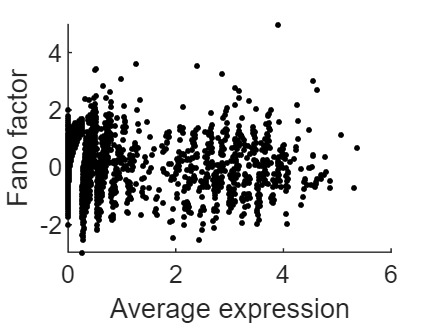

        5041        4000




id = gene_selection(M,iniData);%This section will generate plots to aid reader understanding.

Cell partitioning

%Note that in the Ledein_SNN function, Rscript = 'D:\R\R-4.3.1\bin\Rscript.exe'; is the path to your R installation.
M0 = M(id,:);
K = []; % the cluster numbers can be givn by user.
numCores = 1; 
system_used = 'Mac';
accelerate = 1;%0--------0.9982
label = [];
[group,coph] = partitioning(iniData,M0,K,numCores,system_used,accelerate,label);

Loading required package: Seurat 
The legacy packages maptools, rgdal, and rgeos, underpinning the sp package, 
which was just loaded, will retire in October 2023. 
Please refer to R-spatial evolution reports for details, especially 
https://r-spatial.org/r/2023/05/15/evolution4.html. 
It may be desirable to make the sf package available; 
package maintainers should consider adding sf to Suggests:. 
The sp package is now running under evolution status 2 
     (status 2 uses the sf package in place of rgdal) 
Attaching SeuratObject 
 
Attaching package: 'dplyr' 
 
The following objects are masked from 'package:stats': 
 
    filter, lag 
 
The following objects are masked from 'package:base': 
 
    intersect, setdiff, setequal, union 
 
------------------------------------------------------------------------------ 
You have loaded plyr after dplyr - this is likely to cause problems. 
If you need functions from both plyr and dplyr, please load plyr first, then dplyr: 
library(plyr); lib

K = 3

    0.9949

Clusters of the clustering
